# Ball on Plate Model - LQR

clearvars 

%lineares Model (kontinuirlich)
A = kron(eye(2),[0 1; 0 0]);
const = -5/7*9.81*0.3/2*3.1;
B = kron(eye(2),[0;1])*const;
C = kron(eye(2),[1 0]);
sys = ss(A,B,C,0,0,  'Name'      ,'Ball on Plate - Linear' ,...
                     'StateName' ,["xPos" "xGeschw." "yPos" "yGeschw."],...
                     'OutputName',["X Position","Y Position" ]         ,...
                     'OutputUnit',[     "m"    ,   "m"       ]         ,...
                     'InputName' ,[ "Motor A" "Motor B"      ] ,...
                     'InputUnit' ,[    "rad"    "rad"        ] ,...
                     'TimeUnit'  , 's');
dsys = c2d(sys,1/30);

% LQ-Regler & Vorfilter
Qk = diag([10 0.01 10 0.01]);
Rk = diag([1e-2 1e-2]);
K = dlqr(dsys.A,dsys.B,Qk,Rk);
V = ([1 0 0 0; 0 0 1 0]*((eye(4)-dsys.A+dsys.B*K)^-1)*dsys.B)^-1;

%Model + Beobachter 
extend_dsys = ss(dsys.A,[dsys.B eye(4)],dsys.C,0,1/30                      ,...
                     'Name'      ,'Ball on Plate - Linear'             ,...
                     'StateName' ,["xPos" "xGeschw." "yPos" "yGeschw."],...
                     'OutputName',["X Position","Y Position" ]         ,...
                     'OutputUnit',[     "m"    ,   "m"       ]         ,...
                     'InputName' ,[ "Motor A" "Motor B" 'w1' 'w2' 'w3' 'w4'] ,...
                     'InputUnit' ,[    "rad"    "rad"   ' '  ' '   ' ' ' '  ],...
                     'TimeUnit'  , 's');

[kf_dsys,L] = kalman(extend_dsys,0.8*eye(4),eye(2)*0.01,0);

%Simulink Simulation
sim_data = sim("Modell");
tabl_Fehler = timeseries2timetable(sim_data.get("logsout").get("Fehler").Values);
tabl_fuehrungsgroesse = timeseries2timetable(sim_data.get("logsout").get("w").Values);
tabl_model_out = timeseries2timetable(sim_data.get("logsout").get("y_out").Values);
tabl_kf = timeseries2timetable(sim_data.get("logsout").get("y_kf").Values);

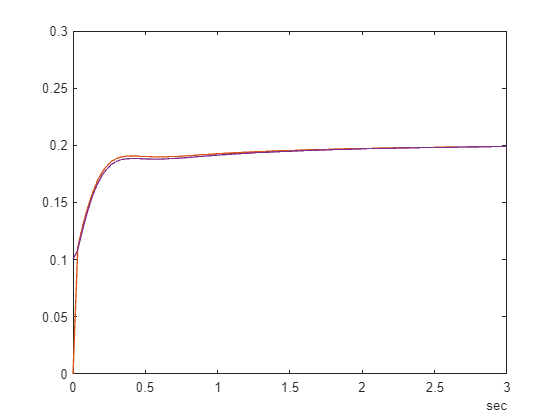

plot(tabl_kf.Time,tabl_kf.y_kf)
hold on
plot(tabl_model_out.Time, tabl_model_out.y_out)
xlim([seconds(0) seconds(3)])
ylim([0 0.3])
hold off

## Messungen

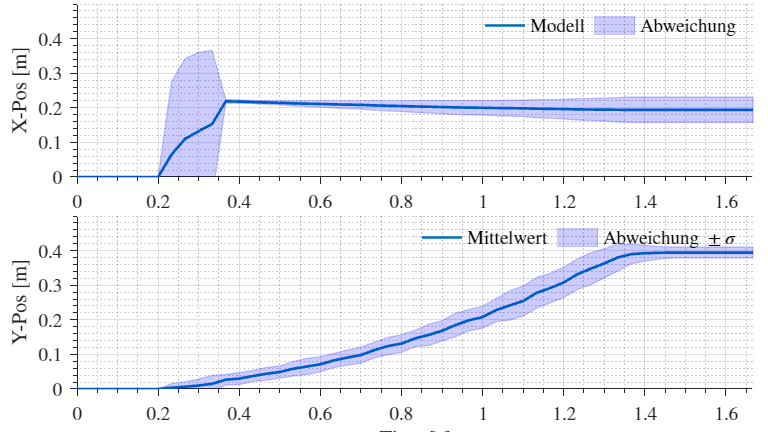

load("dataExp10.mat") %siehe Ordner Messungen, da wird gezeigt wie die Daten erfasst werden

%Experiment Durschnitt und Standardabweichung berechnen
meanX1 = mean(cell2mat(DataObj(:,1,:,:).OutputData),2)';
stdX1 =  2*[std(cell2mat(DataObj(:,1,:,:).OutputData)')];
meanY1 = mean(cell2mat(DataObj(:,2,:,:).OutputData),2)';
stdY1 =  2*[std(cell2mat(DataObj(:,2,:,:).OutputData)')];

u1_rad = mean(cell2mat(DataObj(:,:,1,:).InputData),2)'*pi/180;
u2_rad = mean(cell2mat(DataObj(:,:,2,:).InputData),2)'*pi/180;


t = (0:1/30:(size(meanX1,2)-1)/30);


clf

figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
 
% Create axes
axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
hold(axes1,'on');

% Create plot
plot(t,meanX1,'DisplayName','Modell','LineWidth',2,'LineStyle','-');

patch('XData',[t  fliplr(t)], ...
      'YData',[meanX1+stdX1 fliplr(meanX1-stdX1)], ...
      'FaceColor',[0 0 1],'FaceAlpha',0.2,         ...
      'EdgeColor',[0 0 1],'EdgeAlpha',0.2,         ...
      'DisplayName','Abweichung',HandleVisibility="on");

ylim(axes1,[0 0.5]);
xlim([0 max(t)]);

% Create ylabel
ylabel('X-Pos [m]','FontSize',16,'Interpreter','latex');
 
% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='off');
 
% Uncomment the following line to preserve the Y-limits of the axes
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');


hold(axes1,'off');
% Create axes
axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');

hold(axes2,'on');                         

% Create plot
plot(t,meanY1,'DisplayName','Mittelwert','LineWidth',2,'LineStyle','-');

patch('XData',[t fliplr(t)], ...
      'YData',[meanY1+stdY1 fliplr(meanY1-stdY1)], ...
      'FaceColor',[0 0 1],'FaceAlpha',0.2,         ...
      'EdgeColor',[0 0 1],'EdgeAlpha',0.2,         ...
      'DisplayName','Abweichung $\pm\sigma$',HandleVisibility="on");

 
ylim(axes2,[0 0.5]);
xlim([0 max(t)]);

% Create ylabel
ylabel('Y-Pos [m]','FontSize',16,'Interpreter','latex');


% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex');

legend2 = legend(axes2,'show');
set(legend2,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');
 
hold(axes2,'off');
yreal = [meanX1' meanY1'];
u_rad = [u2_rad' u1_rad'];
clearvars -except yreal u_rad t

## Lineares Model + LQR Regler

A = kron(eye(2),[0 1; 0 0]);
const = -5/7*9.81*0.3/2*3.1;
B = kron(eye(2),[0;1])*const;
C = kron(eye(2),[1 0]);
sys = ss(A,B,C,0,0,  'Name'      ,'Ball on Plate - Linear' ,...
                     'StateName' ,["xPos" "xGeschw." "yPos" "yGeschw."],...
                     'OutputName',["X Position","Y Position" ]         ,...
                     'OutputUnit',[     "m"    ,   "m"       ]         ,...
                     'InputName' ,[ "Motor A" "Motor B"      ] ,...
                     'InputUnit' ,[    "rad"    "rad"        ] ,...
                     'TimeUnit'  , 's');
dsys = c2d(sys,1/30);


Qk = diag([10 0.01 10 0.01]);
Rk = diag([1e-2 1e-2]);
K = dlqr(dsys.A,dsys.B,Qk,Rk);
V = ([1 0 0 0; 0 0 1 0]*((eye(4)-dsys.A+dsys.B*K)^-1)*dsys.B)^-1;

extend_dsys = ss(dsys.A,[dsys.B eye(4)],dsys.C,0,1/30                      ,...
                     'Name'      ,'Ball on Plate - Linear'             ,...
                     'StateName' ,["xPos" "xGeschw." "yPos" "yGeschw."],...
                     'OutputName',["X Position","Y Position" ]         ,...
                     'OutputUnit',[     "m"    ,   "m"       ]         ,...
                     'InputName' ,[ "Motor A" "Motor B" 'w1' 'w2' 'w3' 'w4'] ,...
                     'InputUnit' ,[    "rad"    "rad"   ' '  ' '   ' ' ' '  ],...
                     'TimeUnit'  , 's');

[kf_dsys,L] = kalman(extend_dsys,0.8*eye(4),eye(2)*0.01,0);

%unnötige Variablen löschen
clearvars -except kf_dsys dsys K V L yreal u_rad t

## Kalman Filter

x0 = [yreal(1,2); 0; yreal(1,1); 0];

Unrecognized function or variable 'yreal'.


ymodel = lsim(dsys,u_rad,t,x0);

% 1:2 sind die geschätzten Ausgänge x y
% 3:6 sind die geschätzten Zustände x xdot y ydot
ykf = lsim(kf_dsys,[u_rad yreal]);

clf
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
 
% Create axes
axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
hold(axes1,'on');

% Create plot
plot(t,yreal(:,1),'DisplayName','x-Pos','LineWidth',2,'LineStyle','-');
plot(t,ymodel(:,1),'DisplayName','Modell','LineWidth',2,'LineStyle','-');
plot(t,ykf(:,1),'DisplayName','Filter','LineWidth',2,'LineStyle','-.','Color',[0 1 0]);

ylim(axes1,[0 0.5]);
xlim([0 max(t)]);

% Create ylabel
ylabel('X-Pos [m]','FontSize',16,'Interpreter','latex');
 
% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='off');
 
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');


hold(axes1,'off');
% Create axes
axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');

hold(axes2,'on');                         

% Create plot
plot(t,yreal(:,2),'DisplayName','y-Pos','LineWidth',2,'LineStyle','-');
plot(t,ymodel(:,2),'DisplayName','Modell','LineWidth',2,'LineStyle','-');
plot(t,ykf(:,2),'DisplayName','Filter','LineWidth',2,'LineStyle','-.','Color',[0 1 0]);
 
ylim(axes2,[0 0.5]);
xlim([0 max(t)]);

% Create ylabel
ylabel('Y-Pos [m]','FontSize',16,'Interpreter','latex');


% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex');

legend2 = legend(axes2,'show');
set(legend2,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');
 
hold(axes2,'off');
%clearvars -except ykf ymodel L K V dsys kf_dsys

## Labyrinth Weg

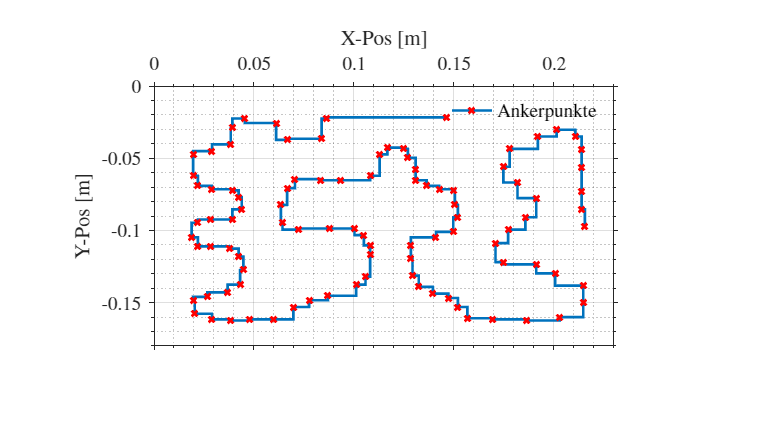

load('labyrinthPfad.mat') %siehe Ordner Messungen, da wird gezeigt wie die Daten erfasst werden
ptx = pt(1:end-4,1)*0.188/240;
pty = pt(1:end-4,2)*0.233/300;
clf
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
 
% Create axes
axes1 = axes('Parent',figure1,'Position',[0.2 0.2 0.6 0.6],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on', ...
             XAxisLocation='top',Box='on');
hold(axes1,'on');

stairs(ptx,-pty,Marker="x",LineWidth=2,MarkerEdgeColor="red", DisplayName='Ankerpunkte')


ylim([-0.18 0])
xlim([0 0.23])
% Create ylabel
ylabel('Y-Pos [m]','FontSize',16,'Interpreter','latex');
 
% Create xlabel
xlabel('X-Pos [m]','Units','normalized','VerticalAlignment','bottom',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='on');
 
legend1 = legend(axes1,'show');
set(legend1,'Orientation','vertical','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');

hold(axes1,'off');

## Simulink Labyrinth Lösung

load('labyrinthPfad.mat')
ptx = pt(1:end-4,1)*0.188/240;
pty = pt(1:end-4,2)*0.233/300;

w = [ptx pty];
open('Modell.slx')

%save ModellOutput out

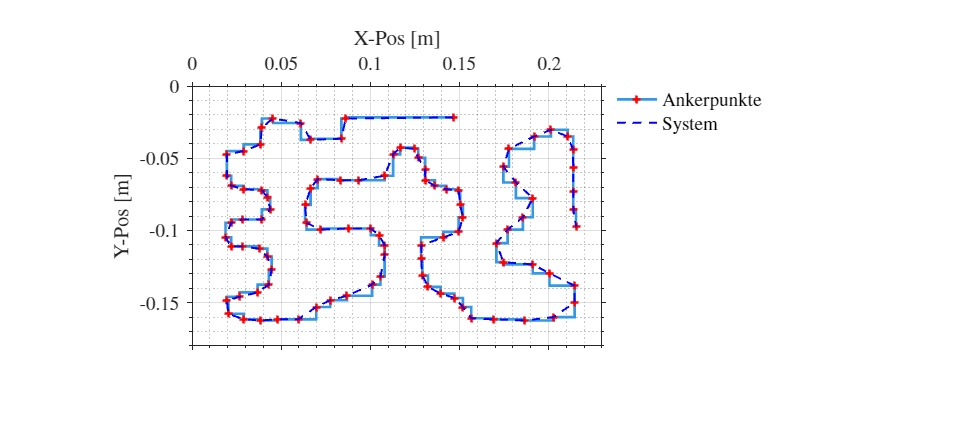

load('ModellOutput.mat')

clf
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.5 0.4]);

% Create axes
axes1 = axes('Parent',figure1,'Position',[0.2 0.2 0.6 0.6],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on', ...
             XAxisLocation='top',Box='on');
hold(axes1,'on');

stairs(ptx,-pty,Marker="+",LineWidth=2,MarkerEdgeColor="red", DisplayName='Ankerpunkte',LineStyle='-',Color=[0.2 0.6 0.9])
plot(out.ymodel.OutputData(:,1),-out.ymodel.OutputData(:,2), DisplayName='System',Marker='none',LineStyle='--',LineWidth=1.5, Color='blue')

ylim([-0.18 0])
xlim([0 0.23])
% Create ylabel
ylabel('Y-Pos [m]','FontSize',16,'Interpreter','latex');
 
% Create xlabel
xlabel('X-Pos [m]','Units','normalized','VerticalAlignment','bottom',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='on');
 
legend1 = legend(axes1,'show');
set(legend1,'Orientation','vertical','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeastoutside');

hold(axes1,'off');

%clearvars -except dsys kf_dsys L K V w


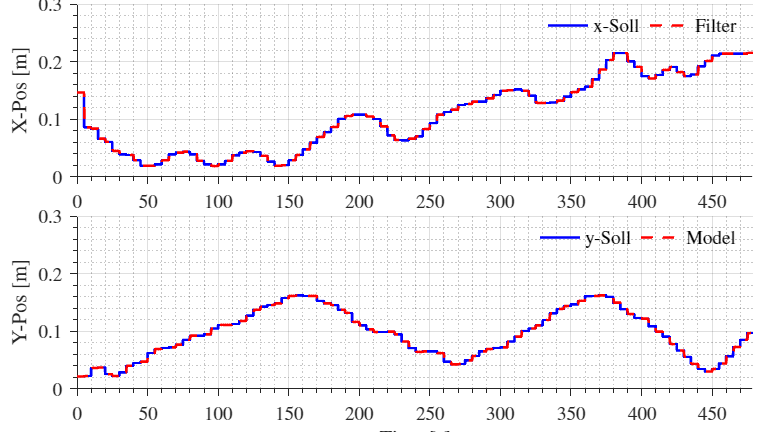

load('ModellOutput.mat')
ykf = out.w_vs_ymodel.OutputData;
w_soll = out.w_vs_ymodel.InputData;
t = 0:1/30:(size(ykf,1)-1)/30;

clf
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
 
% Create axes
axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
hold(axes1,'on');
% Create plot
plot(t,w_soll(:,1),'DisplayName','x-Soll','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
plot(t,ykf(:,1),'DisplayName','Filter','LineWidth',2,'LineStyle','--','Color',[1 0 0]);

ylim(axes1,[0 0.3]);
xlim([0 max(t)]);

% Create ylabel
ylabel('X-Pos [m]','FontSize',16,'Interpreter','latex');
 
% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='off');
 
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');


hold(axes1,'off');
% Create axes
axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');

hold(axes2,'on');                         

% Create plot
plot(t,w_soll(:,2),'DisplayName','y-Soll','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
plot(t,ykf(:,2),'DisplayName','Model','LineWidth',2,'LineStyle','--','Color',[1 0 0]);
 
ylim(axes2,[0 0.3]);
xlim([0 max(t)]);

% Create ylabel
ylabel('Y-Pos [m]','FontSize',16,'Interpreter','latex');


% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex');

legend2 = legend(axes2,'show');
set(legend2,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');
 
hold(axes2,'off');

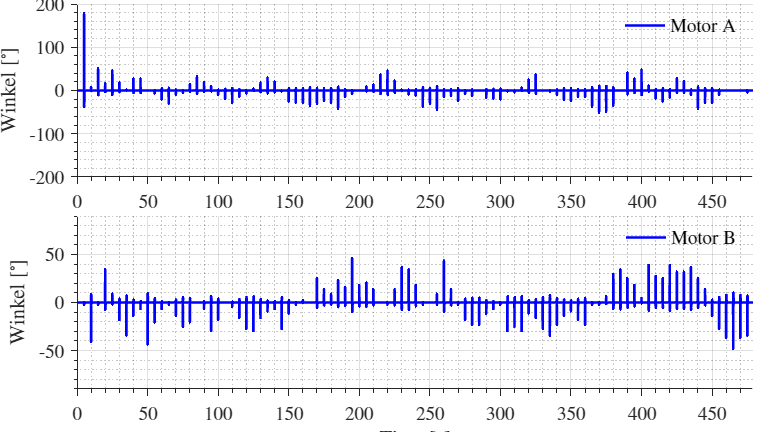

load('ModellOutput.mat')
clf
u = rad2deg(out.ymodel.InputData);
t = 0:1/30:(size(u,1)-1)/30;

clf
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
 
% Create axes
axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
hold(axes1,'on');

% Create plot
plot(t,u(:,1),'DisplayName','Motor A','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
%plot(t,ykf(:,2),'DisplayName','Model','LineWidth',2,'LineStyle','--','Color',[1 0 0]);

ylim([-200 200]);
xlim([0 max(t)]);

% Create ylabel
ylabel('Winkel [$^\circ$]','FontSize',16,'Interpreter','latex');


% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='off');

legend2 = legend(axes1,'show');
set(legend2,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');


hold(axes1,'off');
% axes3 = axes('Parent',figure1,'Position',[0.16 0.55 0.20 0.19],'FontSize',14, ...
%              'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on', ...
%              XTickLabel='');
% hold(axes3,'on');
% % Create plot
% plot(t(1:8:100),u(1:8:100,1),'DisplayName','Motor A','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
% %plot(t,ykf(:,1),'DisplayName','Filter','LineWidth',2,'LineStyle','--','Color',[1 0 0]);
% 
% ylim(axes3,[-200 200]);
% %xlim([0 40]);
% 
% % Create ylabel
% ylabel('Winkel [$^\circ$]','FontSize',16,'Interpreter','latex',Visible='off');
% 
% % Create xlabel
% xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
% 'HorizontalAlignment','center',...
% 'FontSize',16,...
% 'Interpreter','latex',Visible='off');
% 
% % Uncomment the following line to preserve the Y-limits of the axes
% % Create legend
% %legend1 = legend(axes3,'show');
% set(legend1,'Orientation','horizontal','Interpreter','latex',...
% 'FontAngle','italic',...
% 'FontSize',14,...
% 'EdgeColor','none','Color','none','Location','northeast');
% 
% annotation(figure1,'rectangle',...
%     [0.10 0.74 0.03 0.23]);
% 
% hold(axes3,'off');


% % Create axes
axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');

hold(axes2,'on');                         

% Create plot
plot(t,u(1:size(t,2),2),'DisplayName','Motor B','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
%plot(t,ykf(:,2),'DisplayName','Model','LineWidth',2,'LineStyle','--','Color',[1 0 0]);

ylim(axes2,[-90 90]);
xlim([0 max(t)]);

% Create ylabel
ylabel('Winkel [$^\circ$]','FontSize',16,'Interpreter','latex');


% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex');

legend2 = legend(axes2,'show');
set(legend2,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');

hold(axes2,'off');

Gütemaß

sum(out.simout.Data.^2,3)

ans =     9.8856
    5.7637


LQR

sum(out.simout.Data.^2,3)

ans =     9.8856
    5.7637
